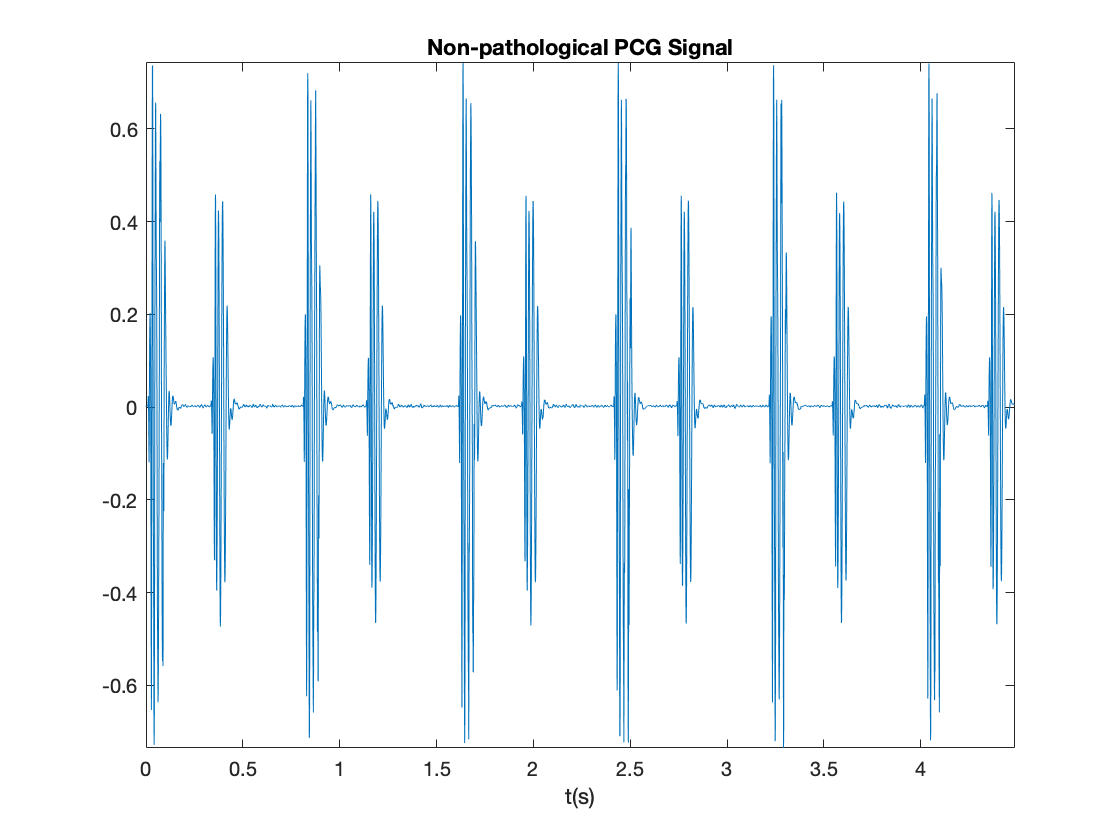

clear

normal = 'Normal_Heart.wav';
sysreg='Systolic_Mitral_Regurgitation_n2.wav';
ejecmur='Ejection_Murmur_n1.wav';
diast= 'Diastolic_Fixed_S2_Split_n1.wav';

[nor,tnorm,fs,player]=leerwav(normal);
title("Non-pathological PCG Signal")

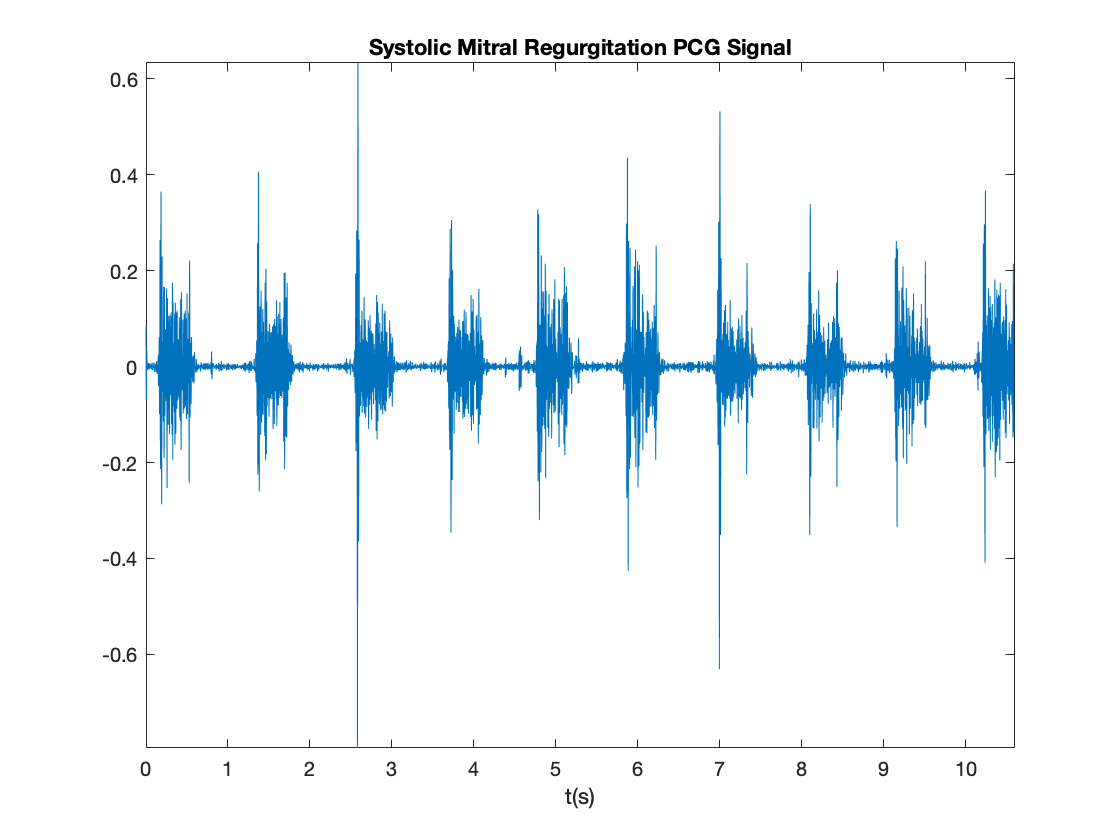

[sysregu,tsys,fs,player]=leerwav(sysreg);
title("Systolic Mitral Regurgitation PCG Signal")

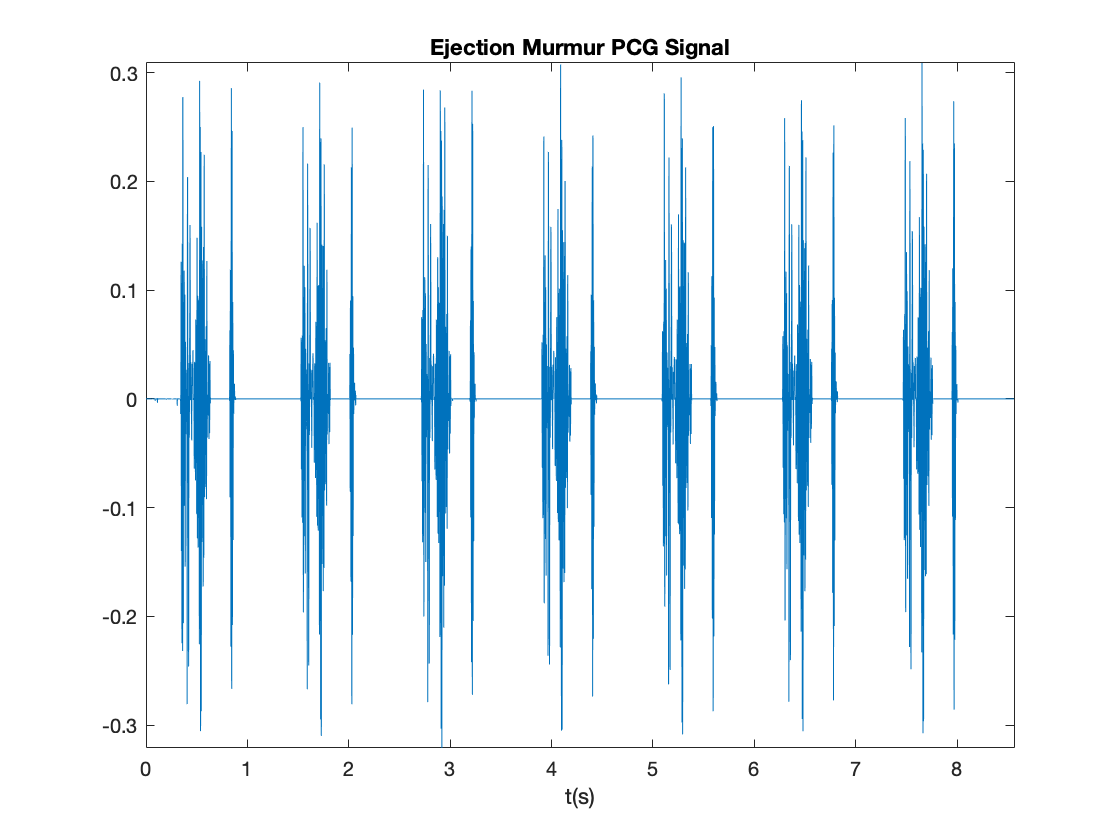

[ejemur,teje,fs,player]=leerwav(ejecmur);
title("Ejection Murmur PCG Signal")

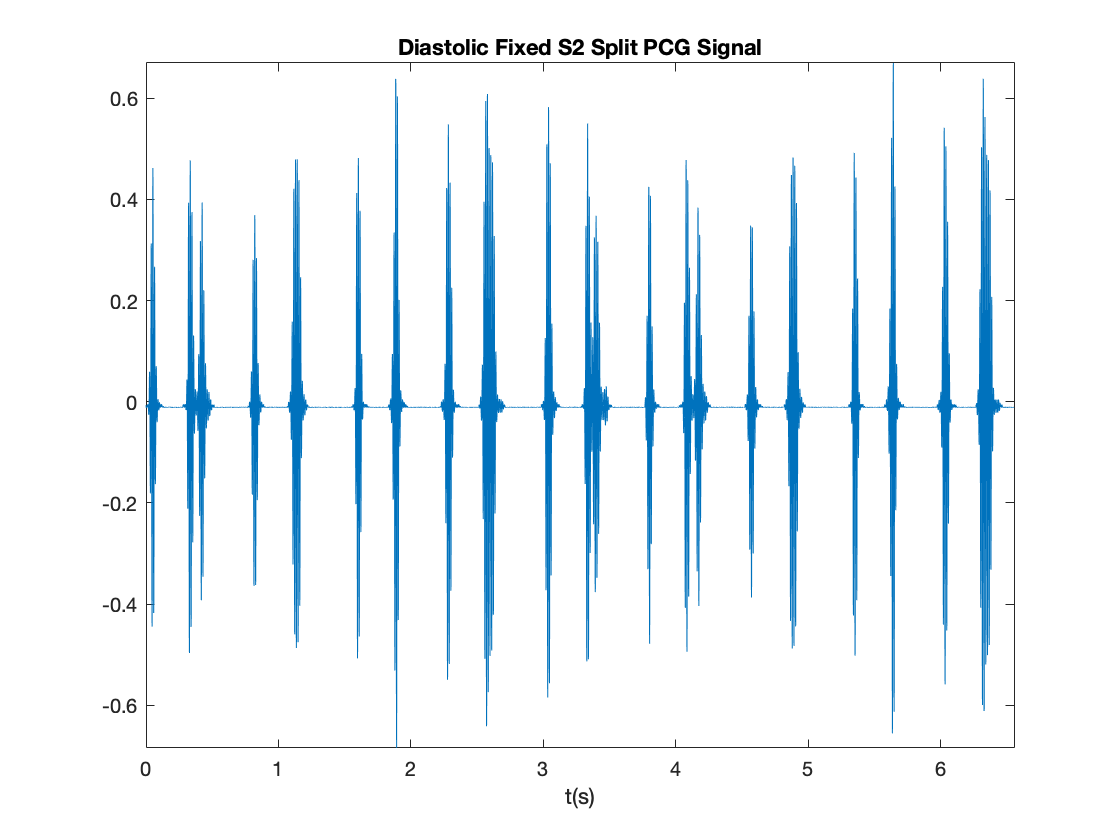

[diast,tdiast,fs,player]=leerwav(diast);
title("Diastolic Fixed S2 Split PCG Signal")

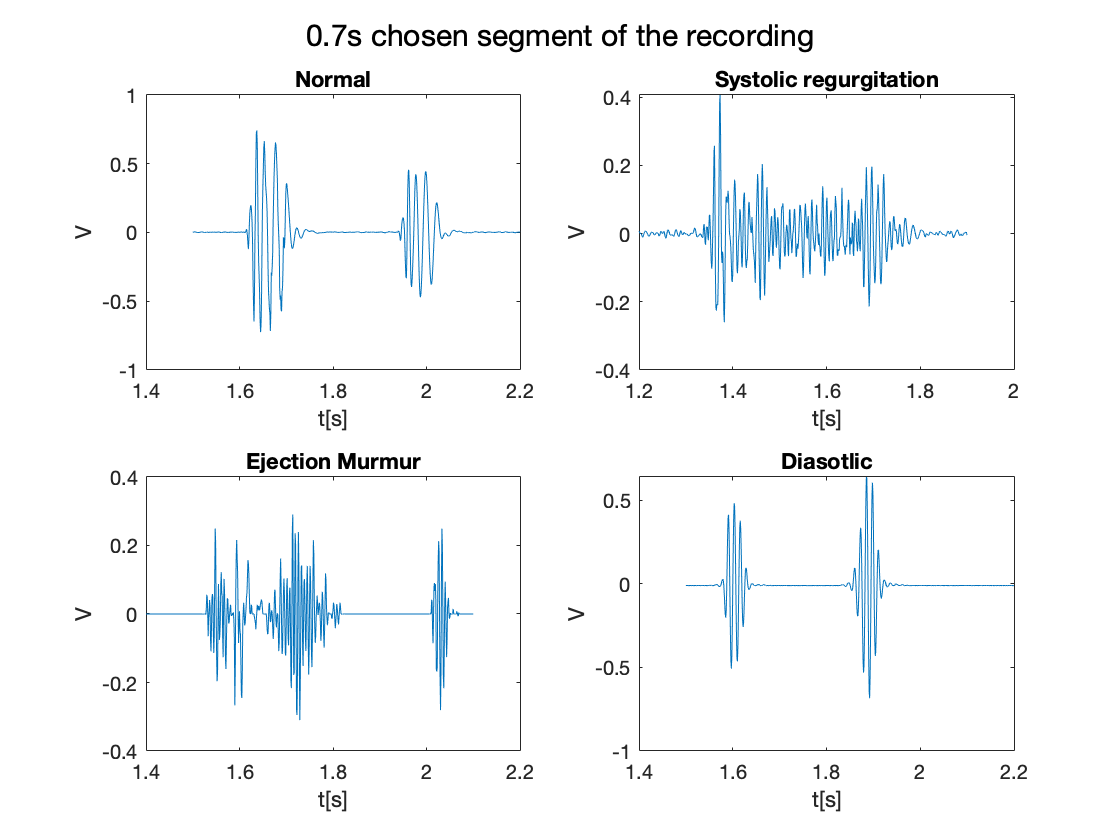

%Para seleccionar sólo los sonidos correspondientes al tercer latido cardíaco:

normal=nor(tnorm>=1.5 & tnorm<=2.2);
t_normal=tnorm(tnorm>=1.5 & tnorm<=2.2);
sysregurg=sysregu(tsys>=1.2 & tsys<=1.9);
t_sysregurg=tsys(tsys>=1.2 & tsys<=1.9);
ejecmur=ejemur(teje>=1.4 & teje<=2.1);
t_ejecmur=teje(teje>=1.4 & teje<=2.1);
diastolic=diast(tdiast>=1.5 & tdiast<=2.2);
t_diastolic=tdiast(tdiast>=1.5 & tdiast<=2.2);

figure(), clf
xlabel("t[s]"); ylabel("V")
sgtitle('0.7s chosen segment of the recording')
subplot 221
plot(t_normal,normal)
title('Normal')
xlabel("t[s]"); ylabel("V")
subplot 222
plot(t_sysregurg,sysregurg)
title('Systolic regurgitation')
xlabel("t[s]"); ylabel("V")
subplot 223
plot(t_ejecmur,ejecmur)
title('Ejection Murmur')
xlabel("t[s]"); ylabel("V")
subplot 224
plot(t_diastolic,diastolic)
title('Diasotlic')
xlabel("t[s]"); ylabel("V")

## **1. En primer lugar, para averiguar el contenido frecuencial de la señal PCG, realiza la estimación de la densidad espectral de potencia de la señal con los métodos de Welch y AR con distintos parámetros para observar las distintas componentes de la señal. **

The criteria which willl be applied to decide the PSD parameters will be that:

- The PSD has clear and distinct peaks, indicating the presence of a dominant frequency in the data

- The PSD should have a smooth and continuous shape, with minimal noise or distortion

### *1.1 Welch Periodogram *

*Hacer funcion que devuelva el periodograma con diferentes parametros...*

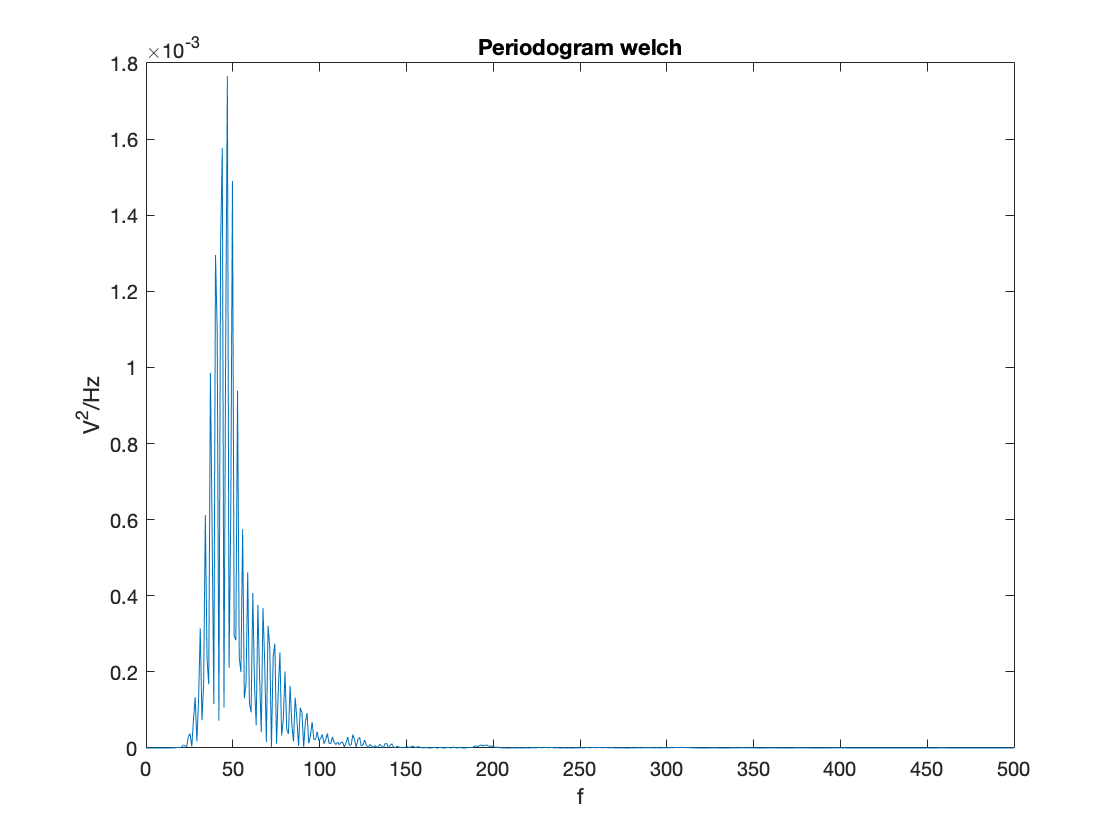

D=0.7*fs;
S=D-1;
NFFT=2^10;

[Pxx_w,f_w]=pwelch(detrend(normal),D,S,NFFT,fs,'onesided'); %Power per frequency

figure(), clf
plot(f_w,Pxx_w)
xlabel('f'),ylabel('V^2/Hz')
title(['Periodogram welch'])

#### 1.1.1 Diastolic Signal

*Changing window magnitude*

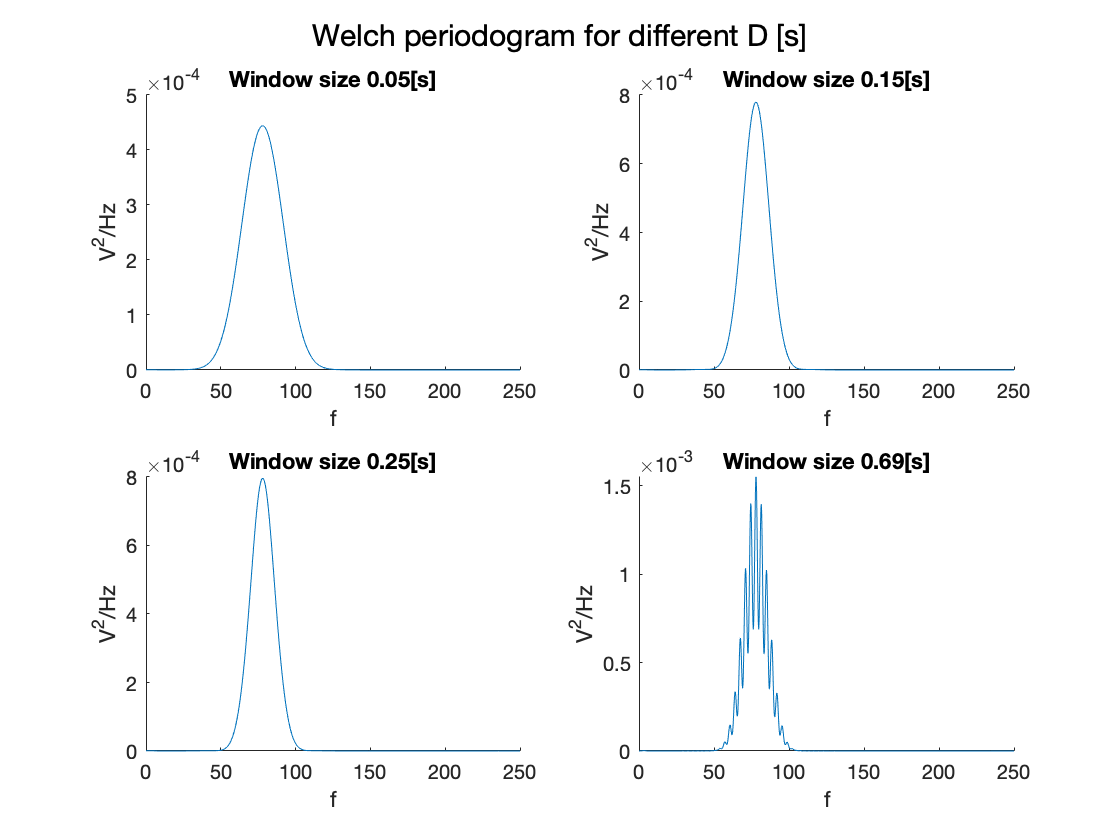

[~]=mypwelchD(diastolic,t_sysregurg, fs, [0.05,0.15,0.25,0.69], 'Welch periodogram for different D [s]')

*Changing Overlapping*

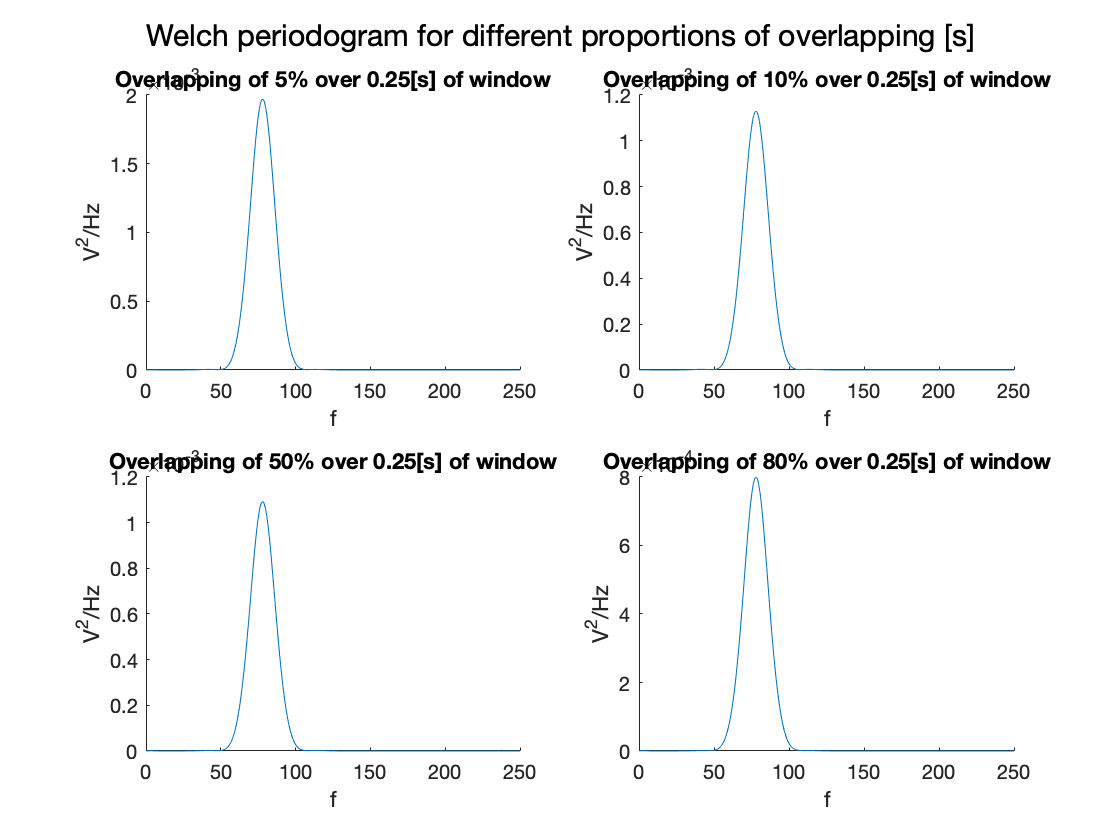

s=[0.05,0.1,0.5,0.8]; % Level of overlapping from 0 to 1
d=0.25; %time width of the window in seconds 
[~]=mypwelchS(diastolic, t_diastolic, fs, d, s, 'Welch periodogram for different proportions of overlapping [s]')

In the normal PCG has a peak of frequency around 80Hz, the size of the window or the degree of overlapping D and S do not substantially modifly the result of the welch periodogram.

#### 1.1.2 Ejection Murmur signal

*Changing window magnitude*

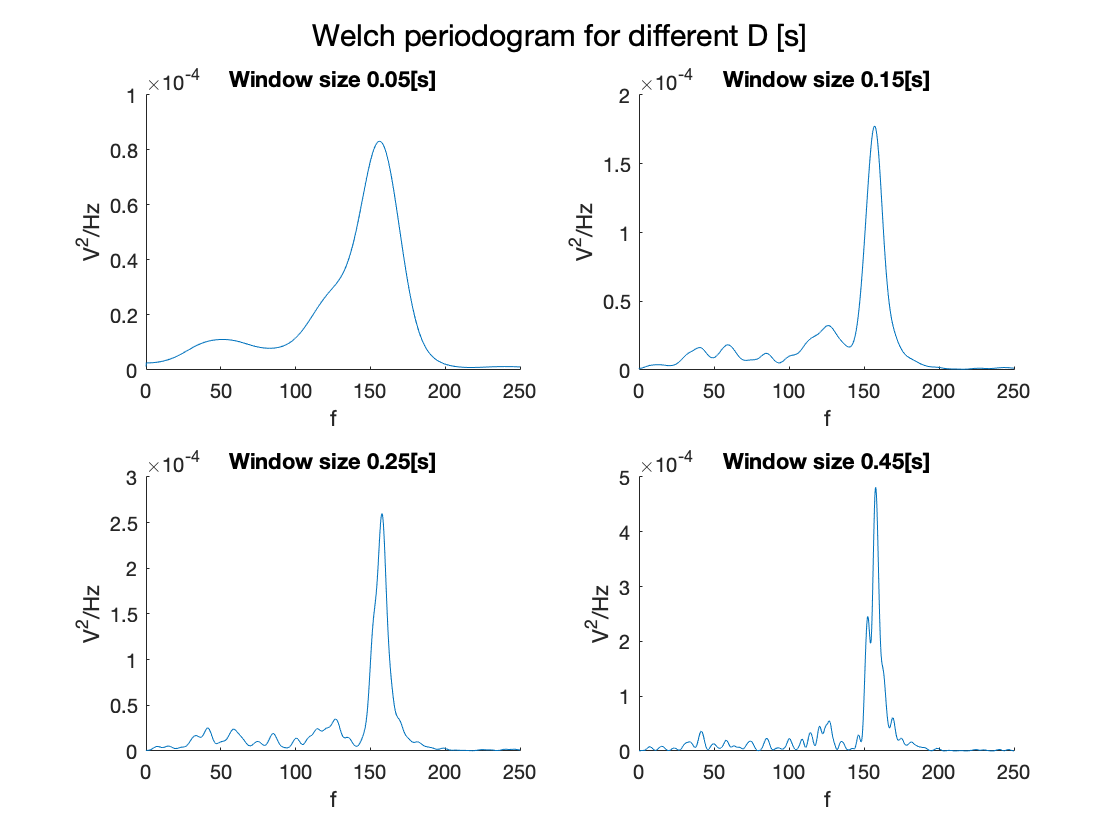

[~]=mypwelchD(ejecmur,t_ejecmur, fs, [0.05,0.15,0.25,0.45], 'Welch periodogram for different D [s]')

*Changing Overlapping*

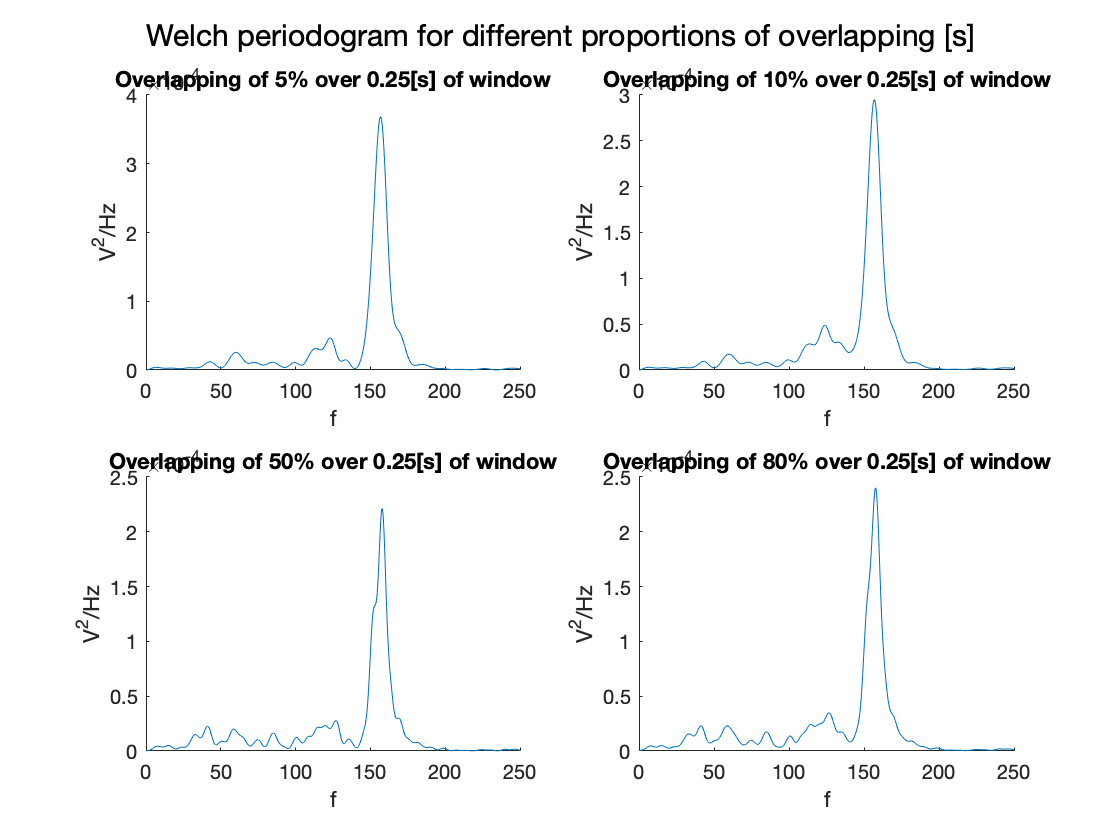

s=[0.05,0.1,0.5,0.8]; % Level of overlapping from 0 to 1
d=0.25; %time width of the window in seconds 
[~]=mypwelchS(ejecmur, t_ejecmur, fs, d, s, 'Welch periodogram for different proportions of overlapping [s]')

D=0.25 has been estimated to be the best window size for Ejection murmu signal, and 50% overlap (s=0.5) shows enough detail of the low frequency contrinutions of the signal, which might be representative of the pathological component of the signal.

#### 1.1.3. Systolic Mitral Regurgitation Signal

*Changing window magnitude*

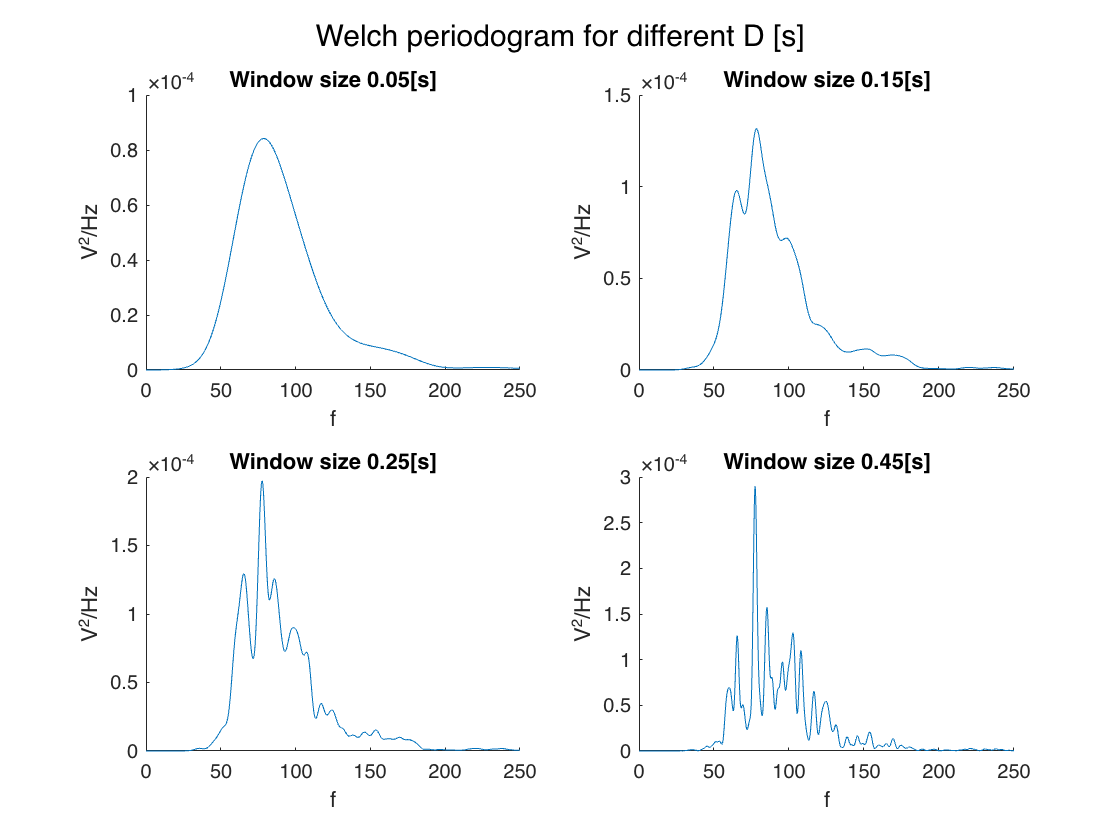

[~]=mypwelchD(sysregurg,t_sysregurg, fs, [0.05,0.15,0.25,0.45], 'Welch periodogram for different D [s]')

*Changing Overlapping*

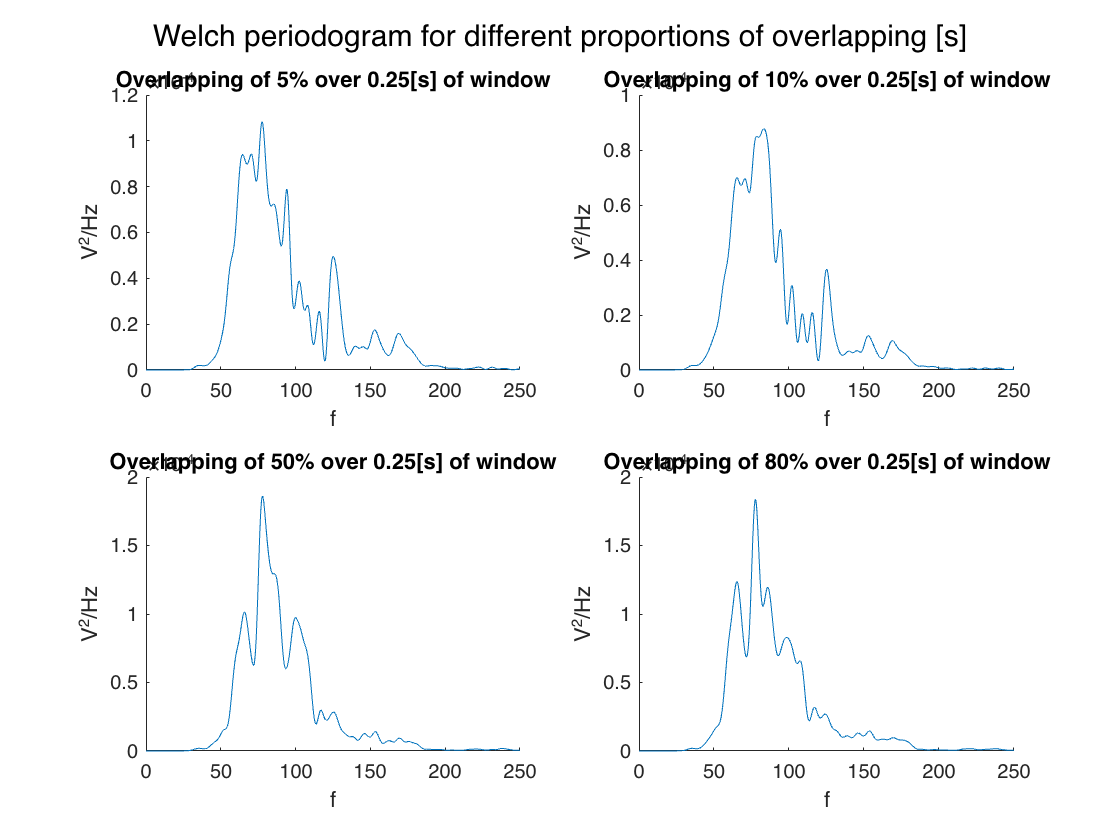

s=[0.05,0.1,0.5,0.8]; % Level of overlapping from 0 to 1
d=0.25; %time width of the window in seconds 
[~]=mypwelchS(sysregurg, t_sysregurg, fs, d, s, 'Welch periodogram for different proportions of overlapping [s]')

The systolic mitral regurgitation signal appears to have the clearest PSD with a windows size of 0.25, as higher values dont differentiate between frequencial peaks. Also, 50% overlapping appears to be the overlapping that best show the three lobes of the central part of the PSD, although not showing enough the 130Hz frequential peak that can be seen in smaller overlappings.

### 1.2 PSD with AR using Burg Method

AR estimation models the system output (biomedical signal: x[n]) as a linear regression of itself (autoregression) plus random noise with zero mean and variance s2 (u[n]). When estimating the model, the values of the samples outside the observation window are not assumed to be zero which allows the model to predict future samples outside the observation window and in accordance with the nature of the process. 

To find the model, the algorithm is usually based on minimizing the optimization condition, commonly the prediction error 𝜌 = sigma^2. Once the model is found, the equivalent frequency response has infinite frequency resolution.

When working with sound signals, the Burg algorithm or the Yule-Walker method are the most common choices for estimating the AR coefficients. The Burg algorithm is an extension of the Yule-Walker method that is particularly well-suited for signals with highly non-stationary characteristics and it can provide a better model for the signal. The Yule-Walker method is based on the autocorrelation function of the signal and it is simple and easy to implement. However it may not be as accurate as the Burg algorithm in certain non-stationary cases.

SOURCE1: Kari Roth, Ismo Kauppinen, Paulo A. A. Esquef, Vesa Valimaki "FREQUENCY WARPED BURG’S METHOD FOR AR-MODELING" in IEEE Explore, 2003

SOURCE2: Abel Torres, "Frequency-Domain Characterization", presentation WS22/23, Universitat de Barcelona/Universitat polytecnica de Barcelona

The `pburg` function in MATLAB is a function that estimates the power spectral density (PSD) of a signal using the Burg method. It takes a sequence of samples of a signal as input and returns an estimate of the PSD as output.

#### 1.2.1 Normal Signal 

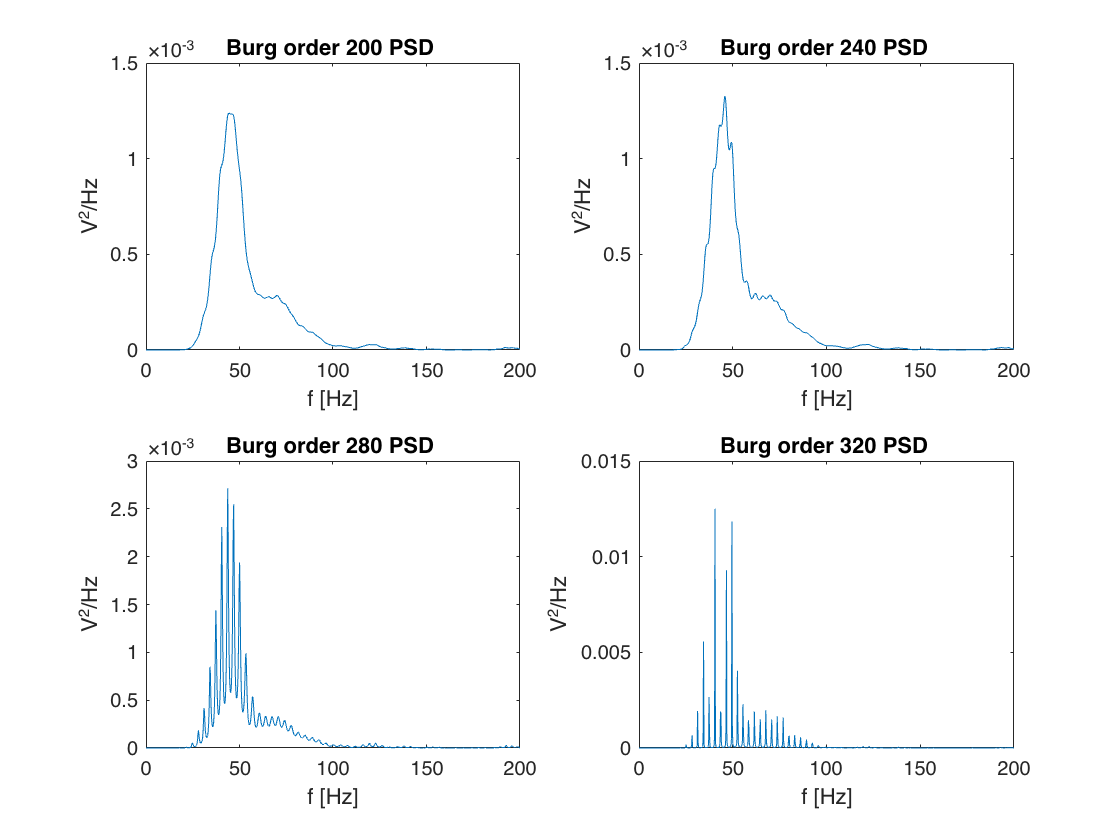

% Calculated Burg PSB for each signal and plot it
% Diastolic PCG:
L = length(normal);
NFFT=2^max(12,nextpow2(L));
count = 0;
Pxx_burg_normal_M = zeros(NFFT/2+1,1);
for order = 200:40:320
    count = count + 1;
    % Estimate PSD using pburg
    [Pxx_burg_normal, f_burg_normal] = pburg(detrend(normal), order, NFFT, 'onesided',fs);
    Pxx_burg_normal_M(:,count) = Pxx_burg_normal;
end

figure()
sizeM = size(Pxx_burg_normal_M);
Nplots = sizeM(2);
for plotN = 1:Nplots
    order = plotN*40 + 160;
    subplot(round(Nplots/2), 2, plotN)
    plot(f_burg_normal,Pxx_burg_normal_M(:,plotN))
    title(['Burg order ' num2str(order) ' PSD '])
    xlabel("f [Hz]")
    ylabel("V^2/Hz")
    xlim([0 200])
end

The order 60 seems to be the one with the best resolution, while maintaining low distortion through noise, which is why this order is chosed for the deatailed PSD parameter calculation using the `psdpar()` function. 

figNumber =   Figure (11: Chapter 4.3: PSD parameters) with properties:

      Number: 11
        Name: 'Chapter 4.3: PSD parameters'
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


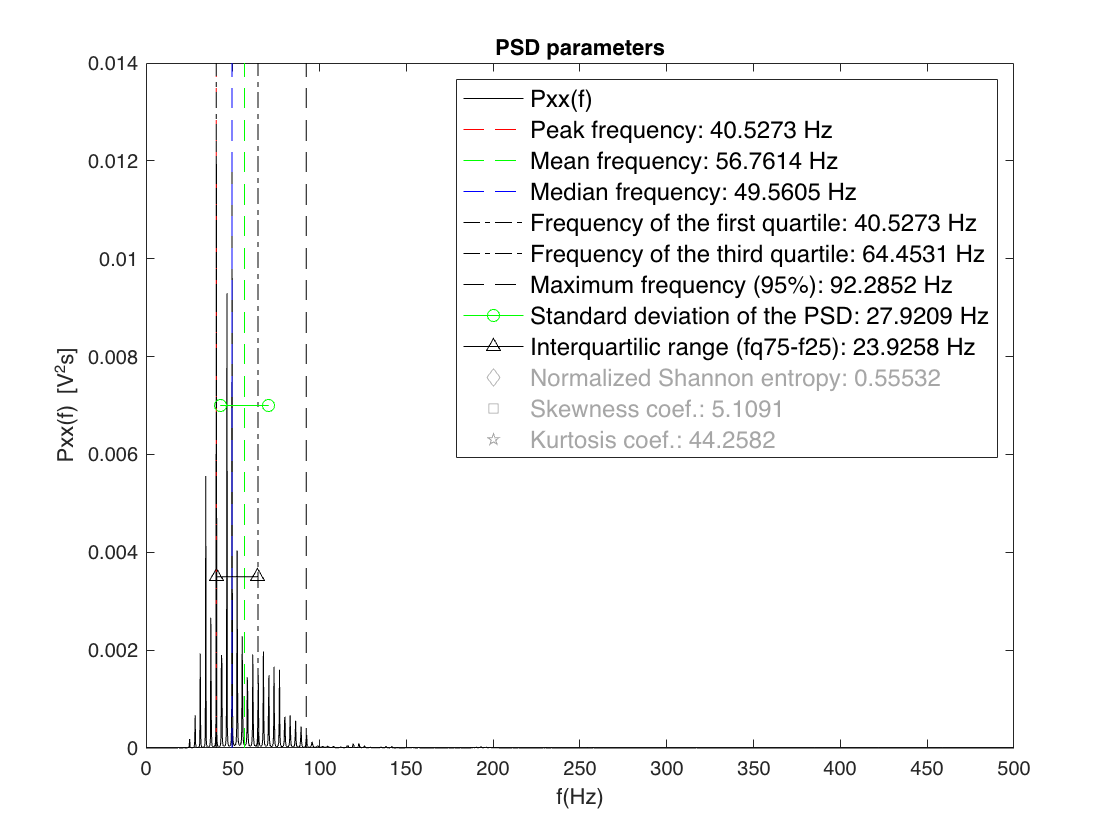

PSDpar_normal = psdpar(Pxx_burg_normal_M(:,4),f_burg_normal,6); 

%%%%%%%%%%%%PSD DESCRPTION + INTERPRETATION

#### 1.2.2 Diastolic Signal

INSERT SIGNAL DETAILS AND FREQ BANDS

The procedure fo

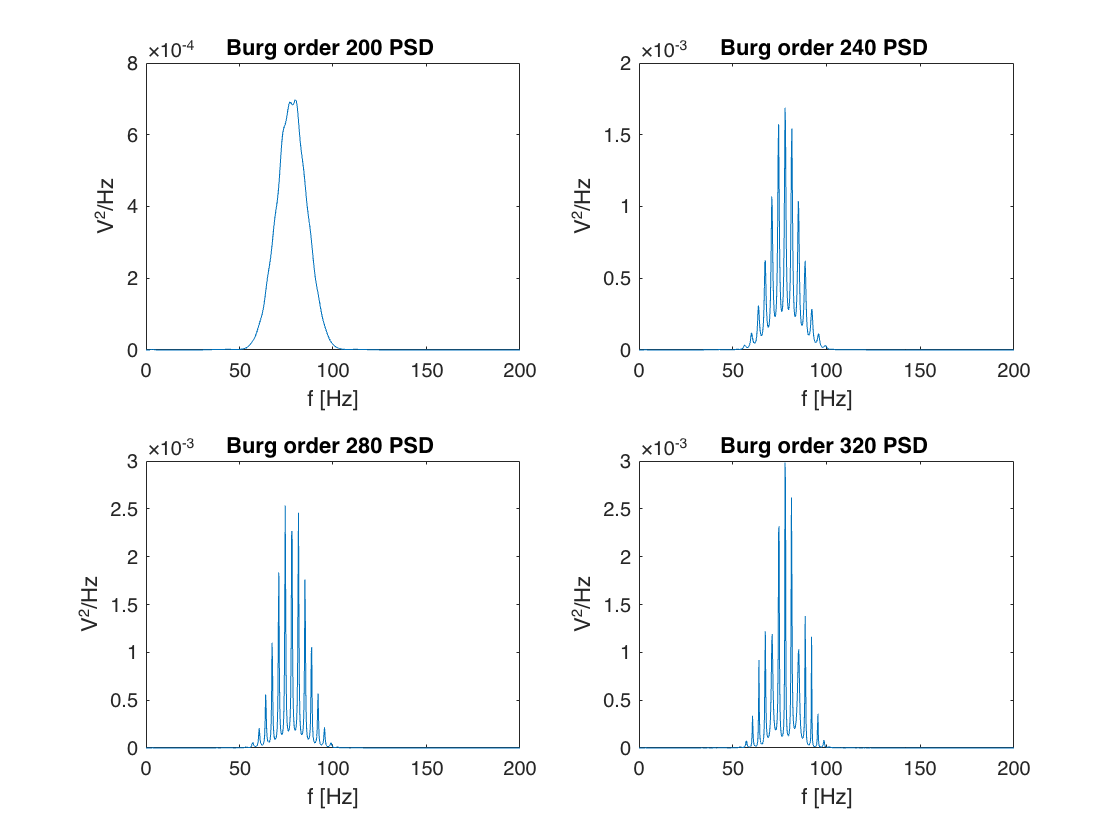

% Calculated Burg PSB for each signal and plot it
% Diastolic PCG:
L = length(diastolic);
NFFT=2^max(12,nextpow2(L));
count = 0;
Pxx_burg_diast_M = zeros(NFFT/2+1,1);
for order = 200:40:320
    count = count + 1;
    % Estimate PSD using pburg
    [Pxx_burg_diast, f_burg_diast] = pburg(detrend(diastolic), order, NFFT, 'onesided',fs);
    Pxx_burg_diast_M(:,count) = Pxx_burg_diast;
end

figure()
sizeM = size(Pxx_burg_diast_M);
Nplots = sizeM(2);
for plotN = 1:Nplots
    order = plotN*40 + 160;
    subplot(round(Nplots/2), 2, plotN)
    plot(f_burg_diast,Pxx_burg_diast_M(:,plotN))
    title(['Burg order ' num2str(order) ' PSD '])
    xlabel("f [Hz]")
    ylabel("V^2/Hz")
    xlim([0 200])
end

The order 10 seems to be the best order for the AR PSD estimation using burg algorithm for the diastolic signal, as it already shows the two main frequency peaks, and no further peaks are revealed when increasing the model order. All PSD of this signal show no noise artifacts. 

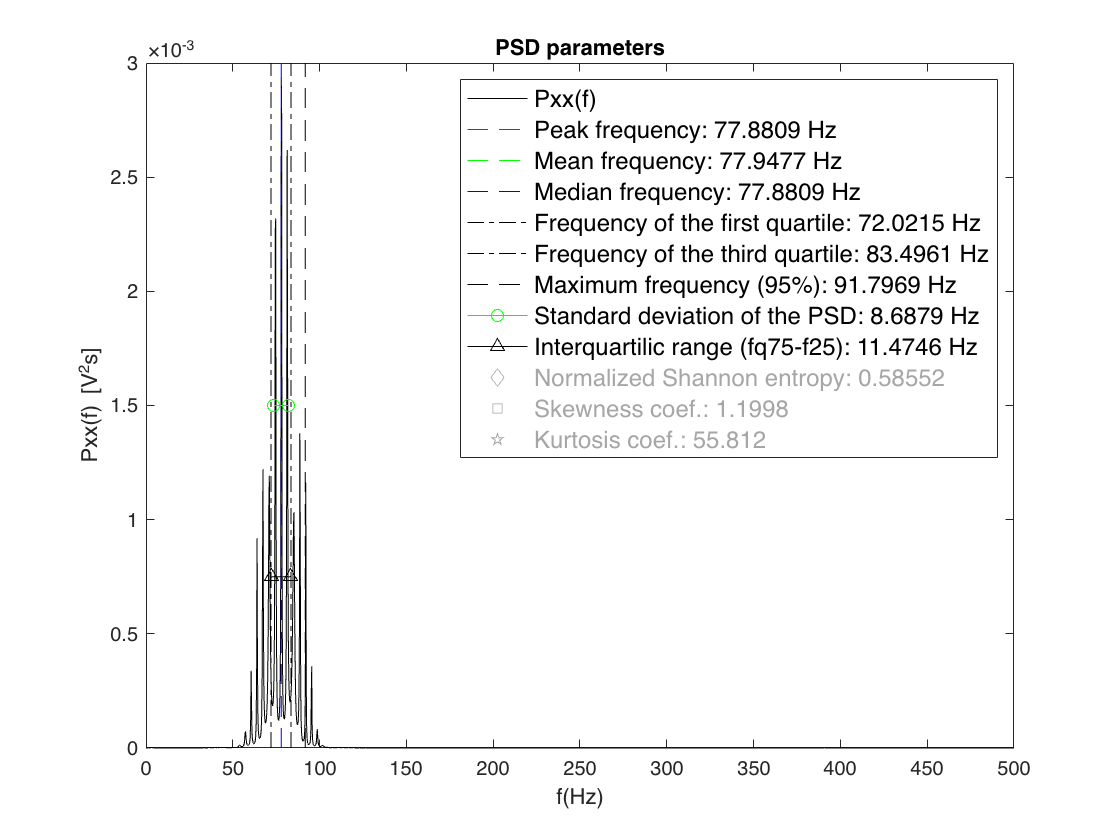

% apply PSD detail function from Abel
PSDpar_diast = psdpar(Pxx_burg_diast_M(:,4),f_burg_diast,6); 

#### 1.2.3 Ejection Murmur signal

A systolic heart murmur is an unusual heart sound that occurs when your heart contracts that can indicate an underlying heart condition. This sound is the result of turbulent blood flow, that can be caused through improper valve openings.

SOURCE3: https://my.clevelandclinic.org/health/diseases/23328-systolic-heart-murmur

Murmurs have higher pitched sound in 100 - 600 Hz range and have a longer duration than normal heart sound. 

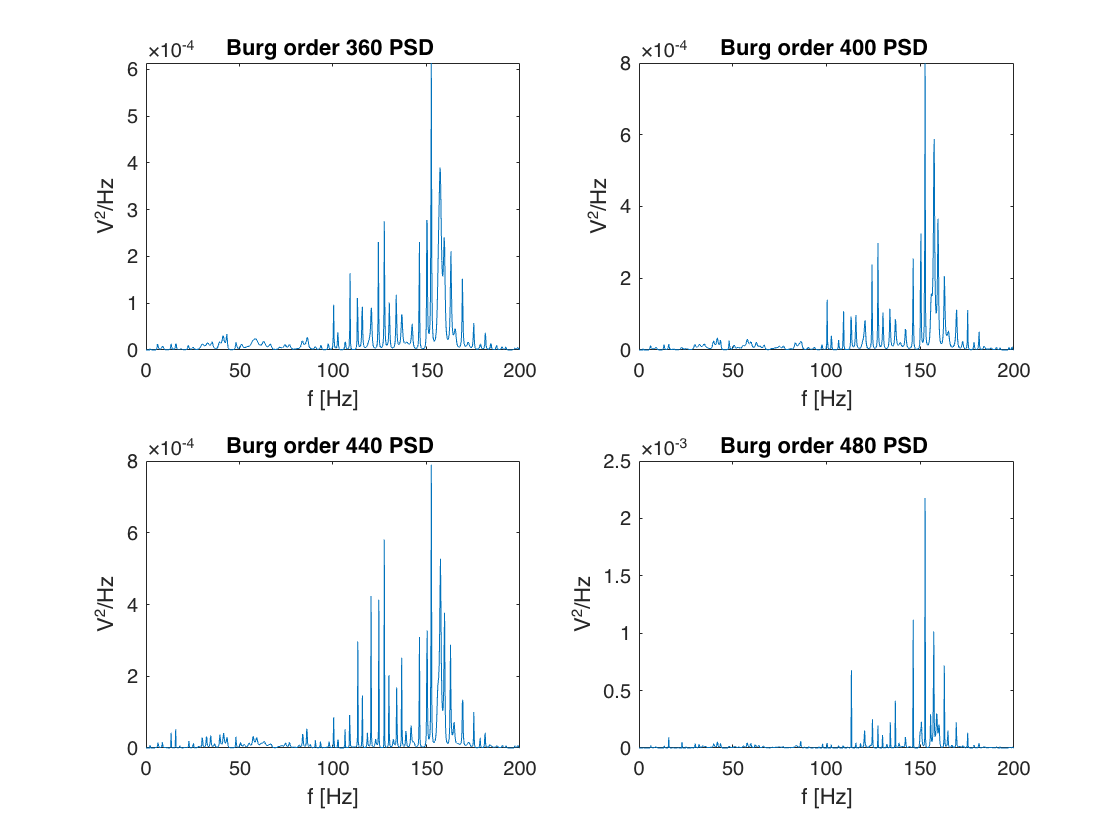

% Calculated Burg PSB for each signal and plot it
% Diastolic PCG:
L = length(ejecmur);
NFFT=2^max(12,nextpow2(L));
count = 0;
Pxx_burg_eject_M = zeros(NFFT/2+1,1);
for order = 360:40:480
    count = count + 1;
    % Estimate PSD using pburg
    [Pxx_burg_eject, f_burg_eject] = pburg(detrend(ejecmur), order, NFFT, 'onesided',fs);
    Pxx_burg_eject_M(:,count) = Pxx_burg_eject;
end

figure()
sizeM = size(Pxx_burg_eject_M);
Nplots = sizeM(2);
for plotN = 1:Nplots
    order = plotN*40 + 320;
    subplot(round(Nplots/2), 2, plotN)
    plot(f_burg_eject,Pxx_burg_eject_M(:,plotN))
    title(['Burg order ' num2str(order) ' PSD '])
    xlabel("f [Hz]")
    ylabel("V^2/Hz")
    xlim([0 200])
end

It is dificult to differentiate between noise peaks and signal peaks. But as the signal is a stochastic signal all the peaks shown in the PSD with order 80 most likely represent parts of the real signal thus hsould be considere. Therefore the PSD with order 80 is analyzed using the psdpar() function.

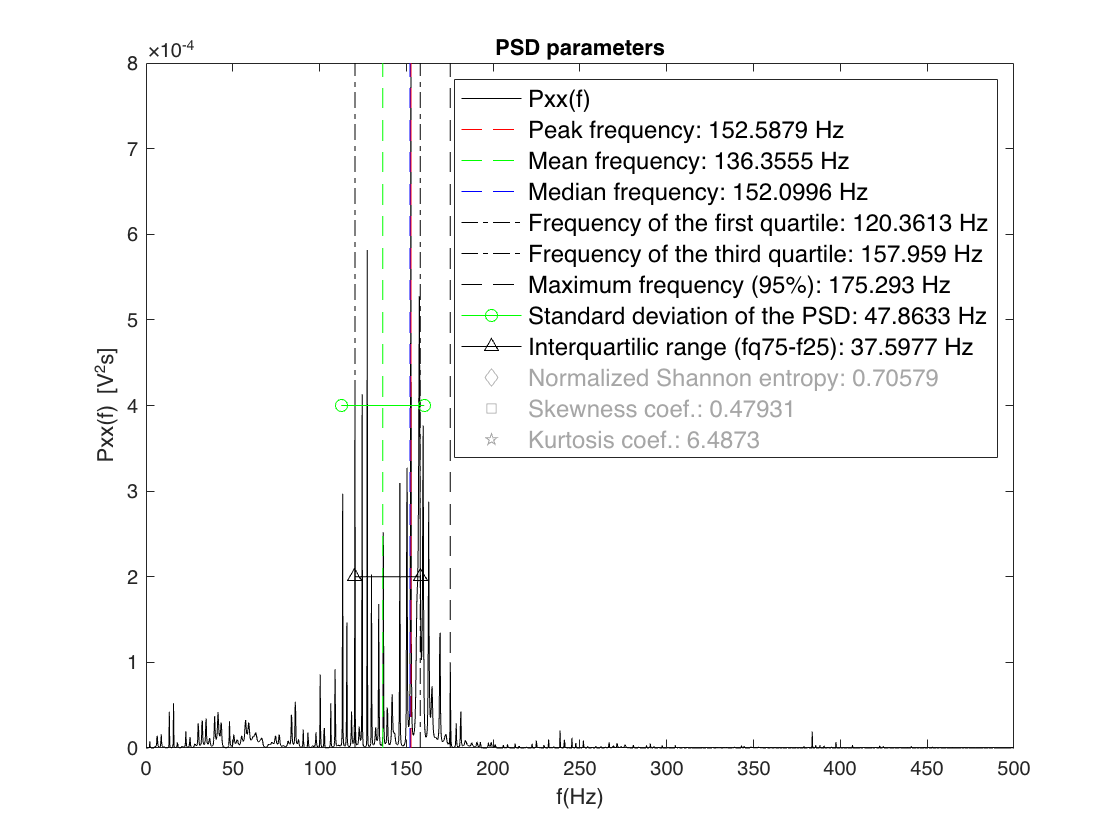

% apply PSD detail function from Abel
PSDpar_eject = psdpar(Pxx_burg_eject_M(:,3),f_burg_eject,6);

#### 1.2.4 Systolic Mitral Regurgitation Signal

Mitral systolic regurgitation (SMR) is a form of heart valve dysfunction characterized by a backflow of blood from the left ventricle into the left atrium during systole (the contraction phase of the heart).

Normally, the mitral valve, which is located between the left atrium and left ventricle, opens to allow blood to flow from the left atrium into the left ventricle, and then closes to prevent blood from flowing back into the left atrium.

In SMR, the mitral valve does not close properly and some blood flows back into the left atrium during systole. This can lead to an increased workload on the left ventricle of the heart, which over time can lead to heart failure.

INSERT SIGNAL DETAILS AND FREQ BANDS

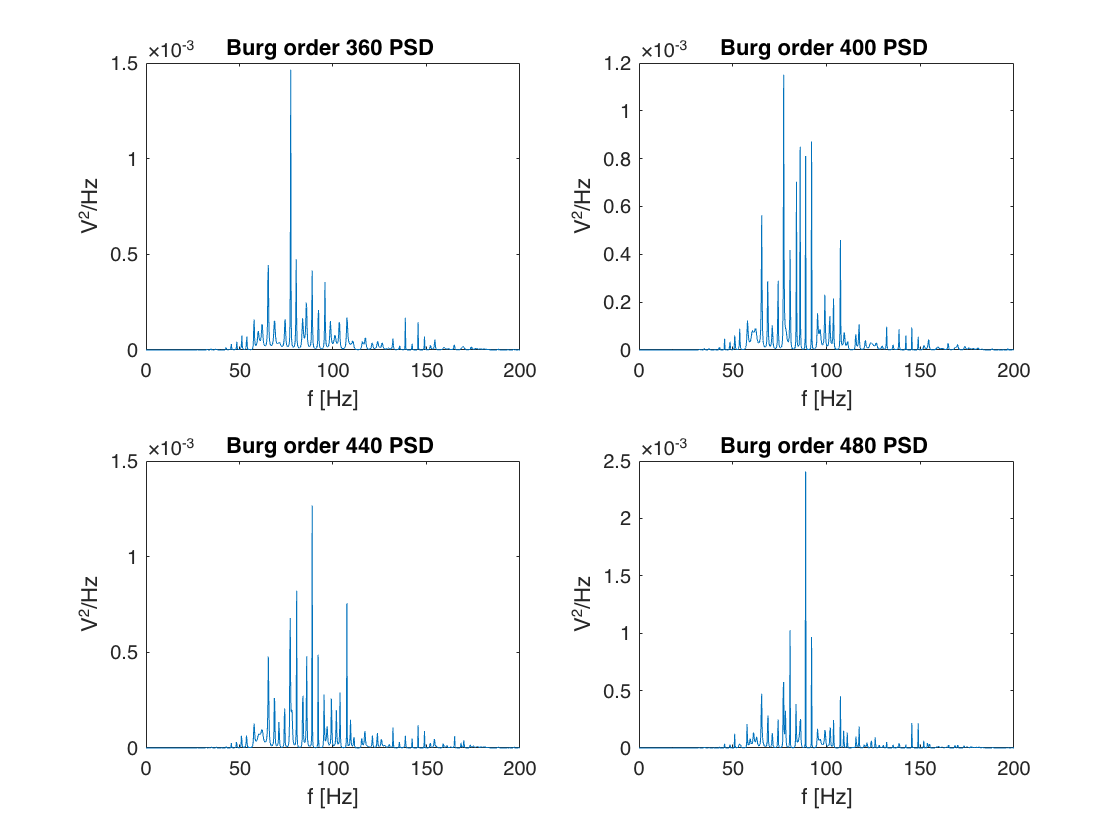

% Calculated Burg PSB for each signal and plot it
% Diastolic PCG:
L = length(sysregurg);
NFFT=2^max(12,nextpow2(L));
count = 0;
Pxx_burg_systo_M = zeros(NFFT/2+1,1);
for order = 360:40:480
    count = count + 1;
    % Estimate PSD using pburg
    [Pxx_burg_systo, f_burg_systo] = pburg(detrend(sysregurg), order, NFFT, 'onesided',fs);
    Pxx_burg_systo_M(:,count) = Pxx_burg_systo;
end

figure()
sizeM = size(Pxx_burg_systo_M);
Nplots = sizeM(2);
for plotN = 1:Nplots
    order = plotN*40 + 320;
    subplot(round(Nplots/2), 2, plotN)
    plot(f_burg_systo,Pxx_burg_systo_M(:,plotN))
    title(['Burg order ' num2str(order) ' PSD '])
    xlabel("f [Hz]")
    ylabel("V^2/Hz")
    xlim([0 200])
end

The PSD with order 60 order looks best to characterize te signal, as it has the highest frequency resolution without noise artifacts.

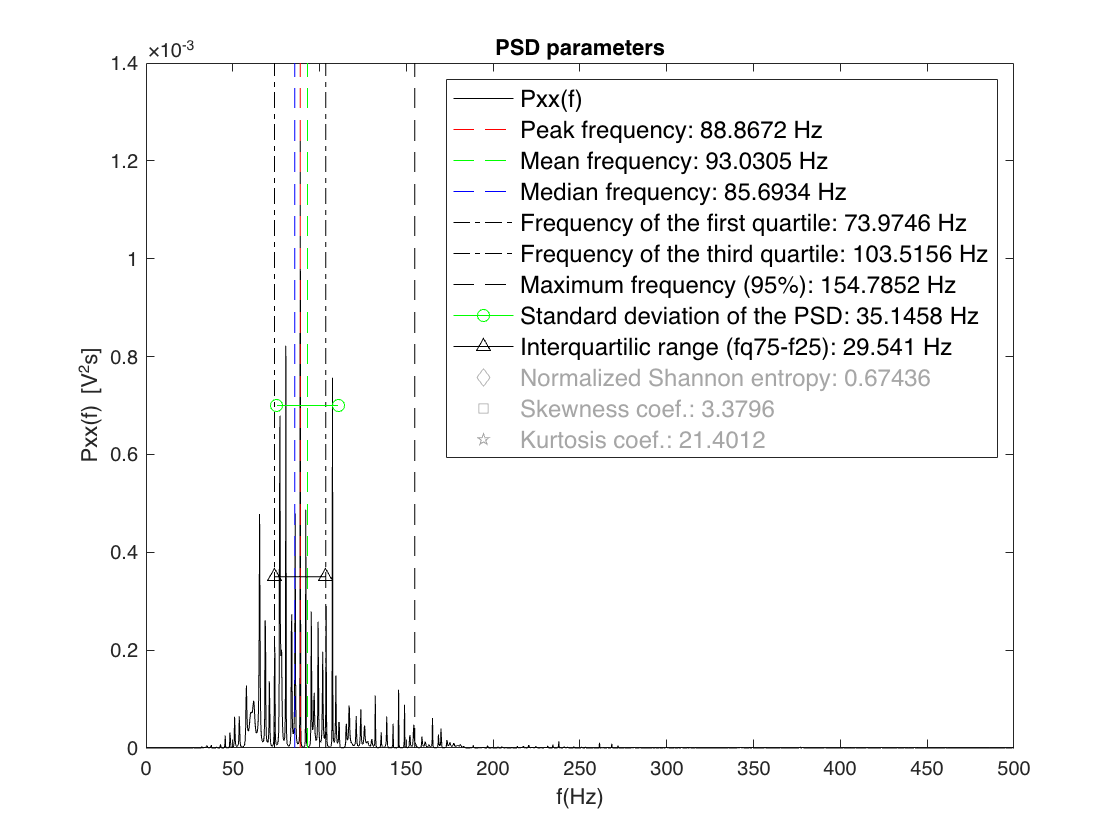

% Use PSD detail function for best PSD
PSDpar_systo = psdpar(Pxx_burg_systo_M(:,3),f_burg_systo,6);

Overall using the Burg Method high orders around 60 were most appropriate for the analysis of the PSD of the normal, ejection murmur and systolic regurgitation. The diastolic signal showed two very characteristical main frequencies, which is why here an order of 10 was already enough to show appropriately characterize the signals PSD.

Whe using the psdpar() function the Shannon entropy showed that there is a high uncertainty of the variable meaning that the prediction has a high uncertainty. 

The skewness coefficient the power spectral density (PSD) plots are positive for all signals, which means that the plot has a longer tail on the high frequency side than on the low frequency side. It is a measure of the asymmetry of the distribution of the power around the center frequency of the signal. It can be used to describe the deviation of the PSD plot from a symmetric bell-shaped curve. 

For the systolic and normal signal this is due to the signals components but could be also influenced by high frequency noise. In case ot the murmur signal, this is misleading as most components are distributed in the lower frequency side of the main frequency. The diastloic skweness value was the lowest because the shape of the PSD was the most symmetric one.

**TABLE:**

**0.98 Hz Max frequ SYSTO**

**1.11 Hz Max frequ EJECT **

**0.566 Hz Max Frequ DIAST**

**0.565 Hz Max Frequ NORM**

Normal and diastolic signal were very similar in the PSD main frequency and also in shape. The difference that the normal signal had more frequency components higher than 0.56 Hz could have been through noise and thus not a clear criteria to distinguish between the two signals.

The PSD of the ejection murmur and systolic pathologies are different in shape and main frequency which means that the PSD can be used to classify systolic regurgitation and the ejection murmur signal. 

## **2. Para ver la distribución temporal del contenido frecuencial de cada componente, analiza las distintas estimaciones de la distribución tiempo-frecuencia de la energía de las señales PCG. Puedes utilizar los programas de Matlab proporcionados en el curso para el cálculo de las RTFs **

Yo haria el spectograma reasignado, el scalograma (myscalogram) y una funcion que devuelva todos los de la clase cohen+wignerwille. (ambiguity)

Hay que tener claro cuales son las diferencias entre ellos

### *2.1 Spectogram (STFT)*						

The SPEC is a useful and very popular T-F representation, but it has limitations when the analyzed signal has components with a variable time-frequency product: 				D*t*×D*f *=*cte *

*The analysis will be performed changing the parameter D (size of the window used) and the type of window (only rectangular and hamming will be delivered, as are the ones more different between them.*

#### 2.1.1 Diastolic Signal

*Rectangular (and non reassigned)*

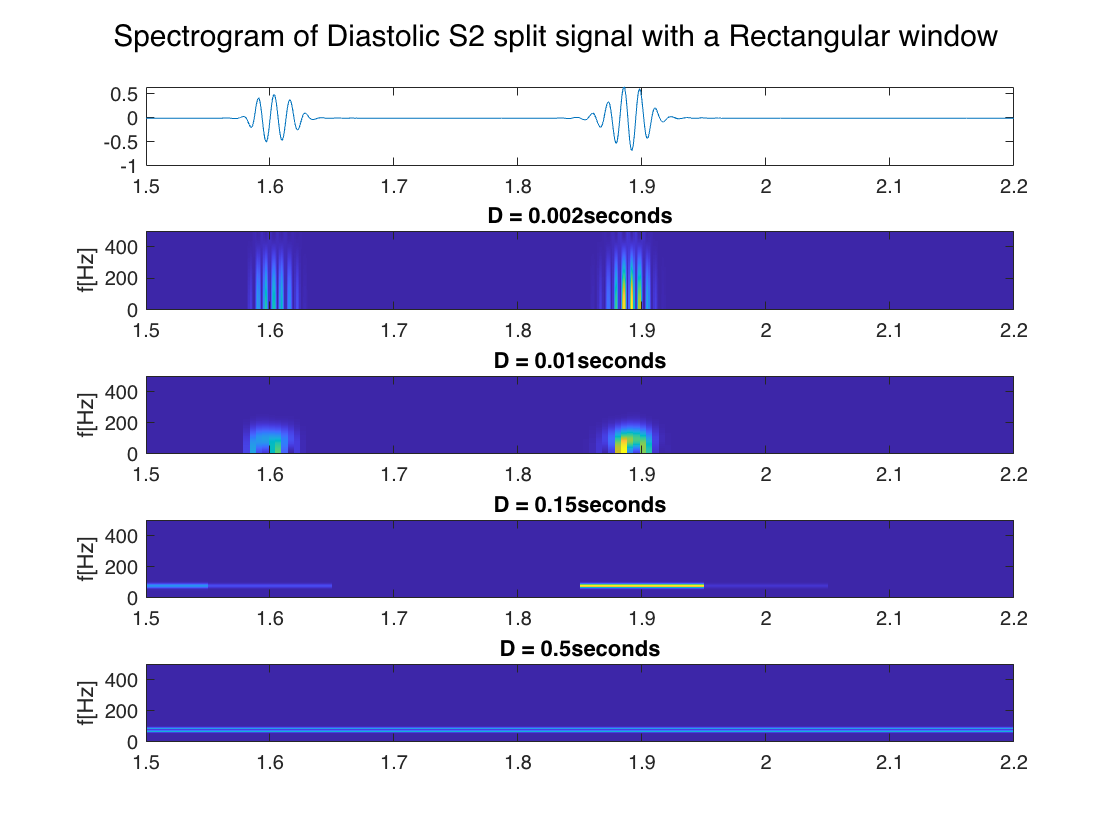

Nridges=0;
fdetection=0;

D= [0.002,0.01,0.15,0.5]*fs;

penval=1;
reassign=0; %Reassigned
umbral = 0; %No threshold
type=0; %0 for rectangular and 1 for hamming

signaltype='Diastolic S2 split';
windowtype = 'Rectangular';
myspectogram(diastolic,fs,t_diastolic,D, type, umbral, penval, Nridges, fdetection, reassign, signaltype, windowtype)

*Hamming (and reassigned)*

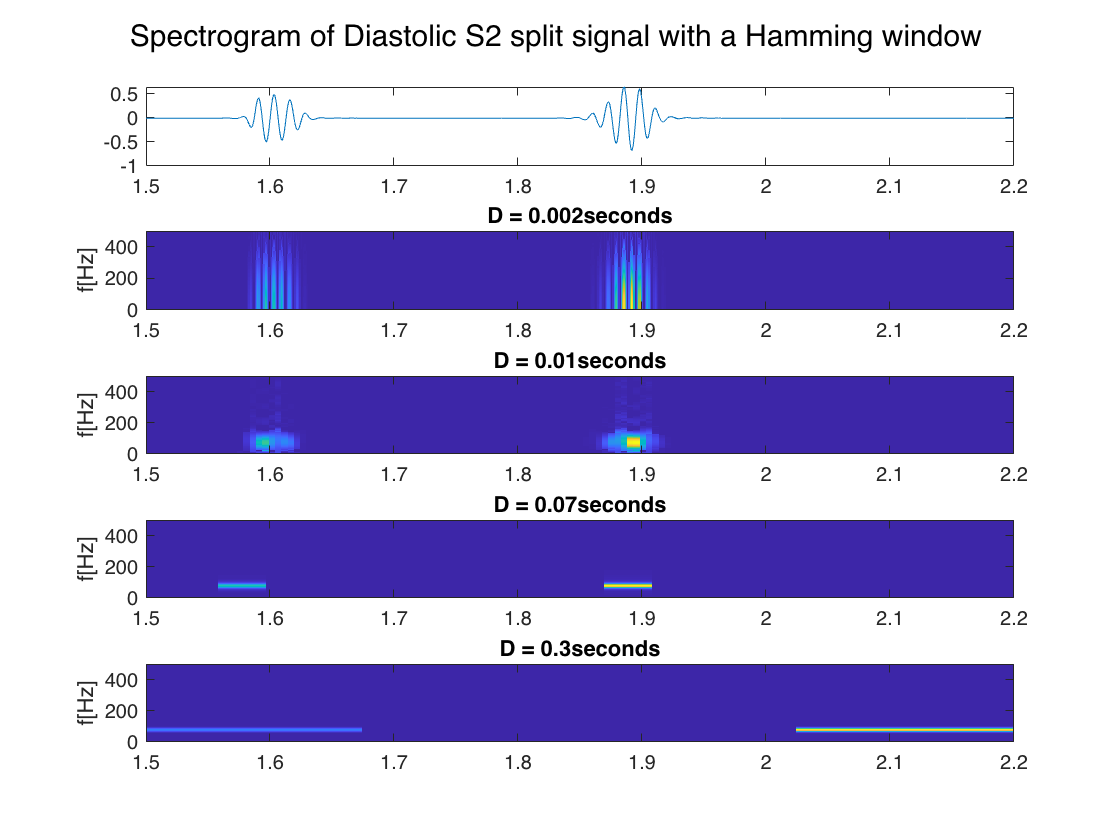

Nridges=0;
fdetection=0;

D= [0.002,0.01,0.07,0.3]*fs;

penval=1;
reassign=1; %Reassigned
umbral = 0; %No threshold
type=1; %0 for rectangular and 1 for hamming

signaltype='Diastolic S2 split';
windowtype = 'Hamming';
myspectogram(diastolic,fs,t_diastolic,D, type, umbral, penval, Nridges, fdetection, reassign, signaltype, windowtype)

It is visible that the frequency is around 75Hz for both sounds.

Between reassigned and not reassigned and hamming and rectangular windows, we can observe that for the same time resolution (let's say 0.1 seconds window) the frequency resolution is a bit better for tha hamming window, as would be expected. There is no visible difference between reassigned and normal spectogram.

#### 2.1.2 Ejection Murmur signal

*Rectangular (and non reassigned)*

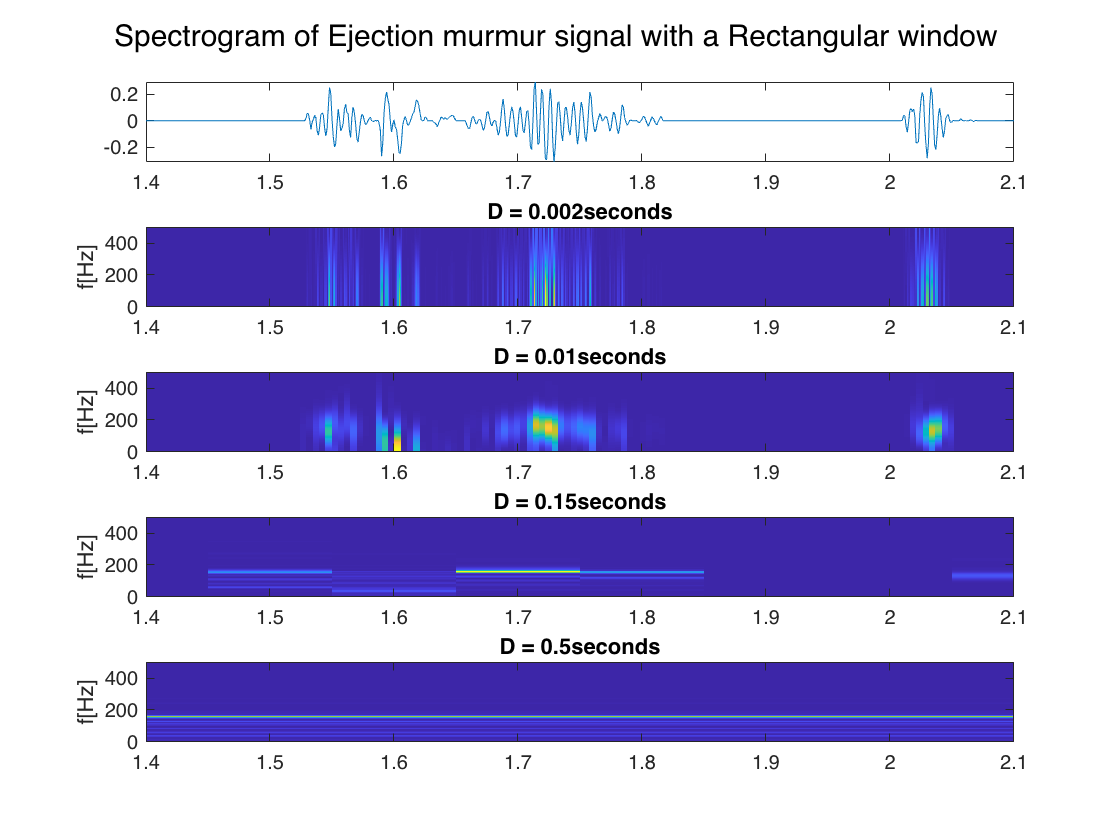

Nridges=0;
fdetection=0;

D= [0.002,0.01,0.15,0.5]*fs;

penval=1;
reassign=0; %Reassigned
umbral = 0; %No threshold
type=0; %0 for rectangular and 1 for hamming

signaltype='Ejection murmur';
windowtype = 'Rectangular';
myspectogram(ejecmur,fs,t_ejecmur,D, type, umbral, penval, Nridges, fdetection, reassign, signaltype, windowtype)

*Hamming (and reassigned)*

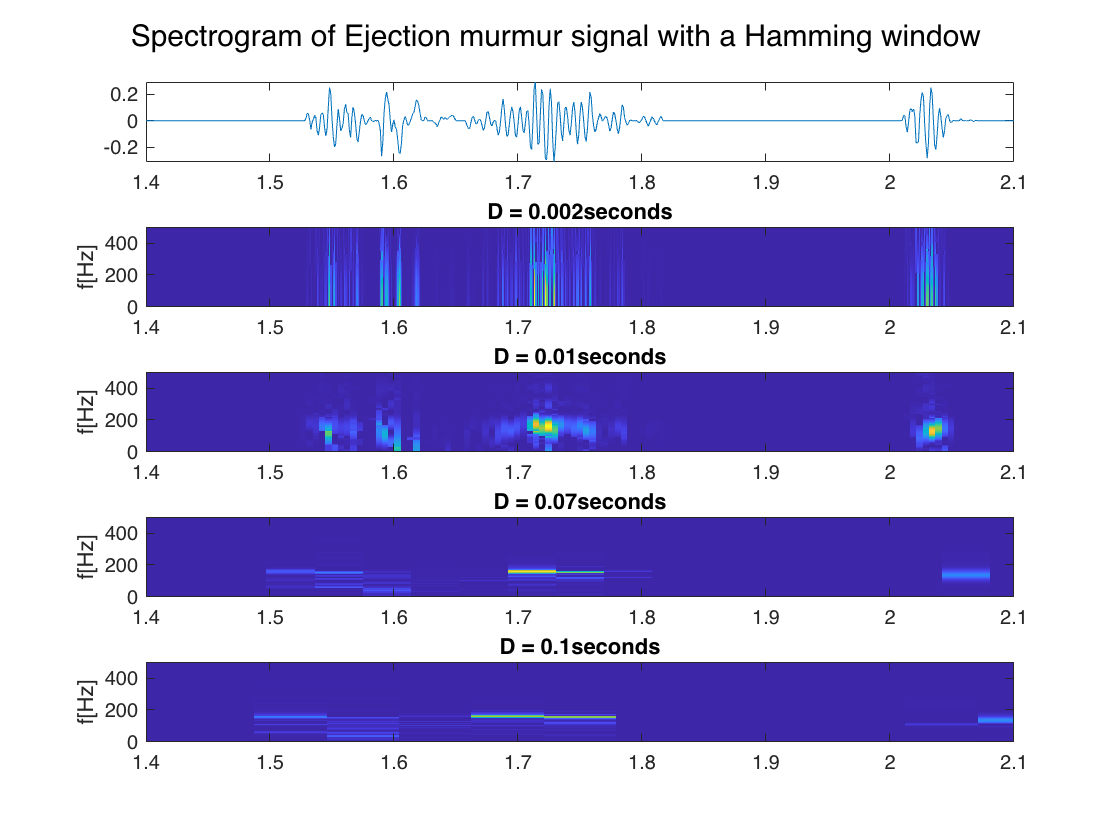

Nridges=0;
fdetection=0;

D= [0.002,0.01,0.07,0.1]*fs;

penval=1;
reassign=1; %Reassigned
umbral = 0; %No threshold
type=1; %0 for rectangular and 1 for hamming

signaltype='Ejection murmur';
windowtype = 'Hamming';
myspectogram(ejecmur,fs,t_ejecmur,D, type, umbral, penval, Nridges, fdetection, reassign, signaltype, windowtype)

#### 2.1.3. Systolic Mitral Regurgitation Signal

*Rectangular (and non reassigned)*

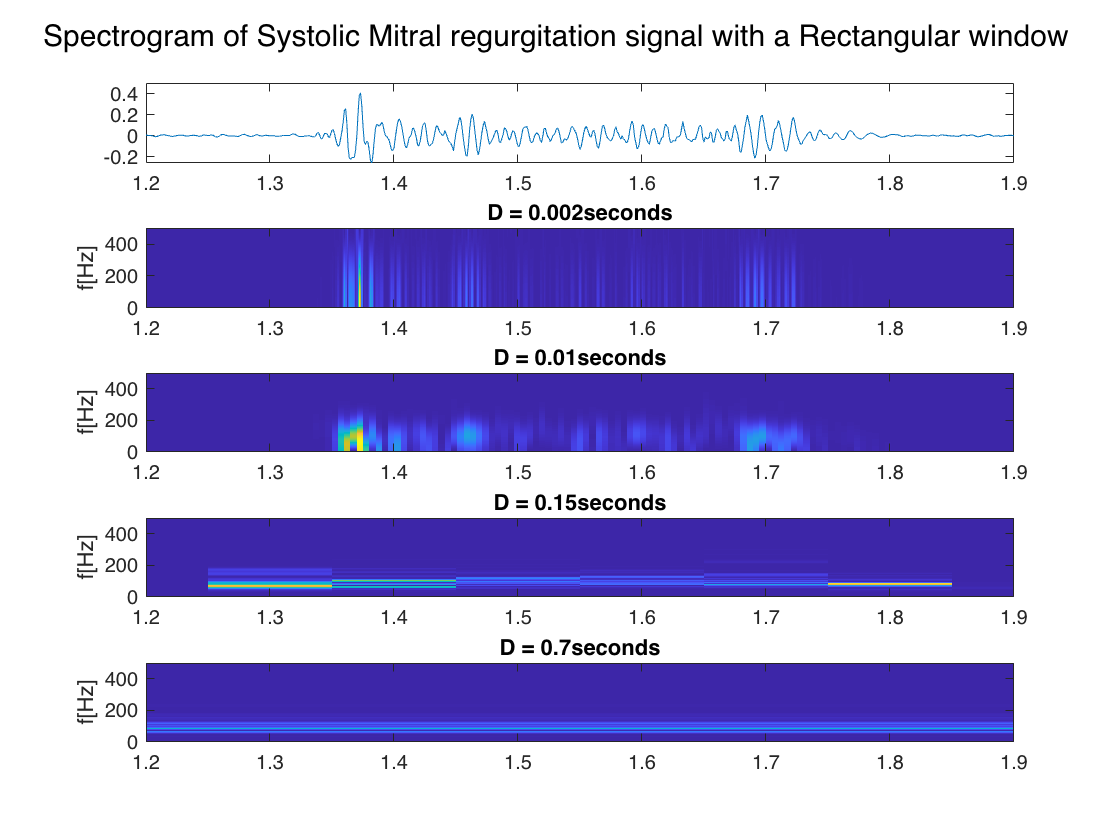

Nridges=0;
fdetection=0;

D= [0.002,0.01,0.15,0.7]*fs;

penval=1;
reassign=0; %Reassigned
umbral = 0; %No threshold
type=0; %0 for rectangular and 1 for hamming

signaltype='Systolic Mitral regurgitation';
windowtype = 'Rectangular';
myspectogram(sysregurg,fs,t_sysregurg,D, type, umbral, penval, Nridges, fdetection, reassign, signaltype, windowtype)

*Hamming (and reassigned)*

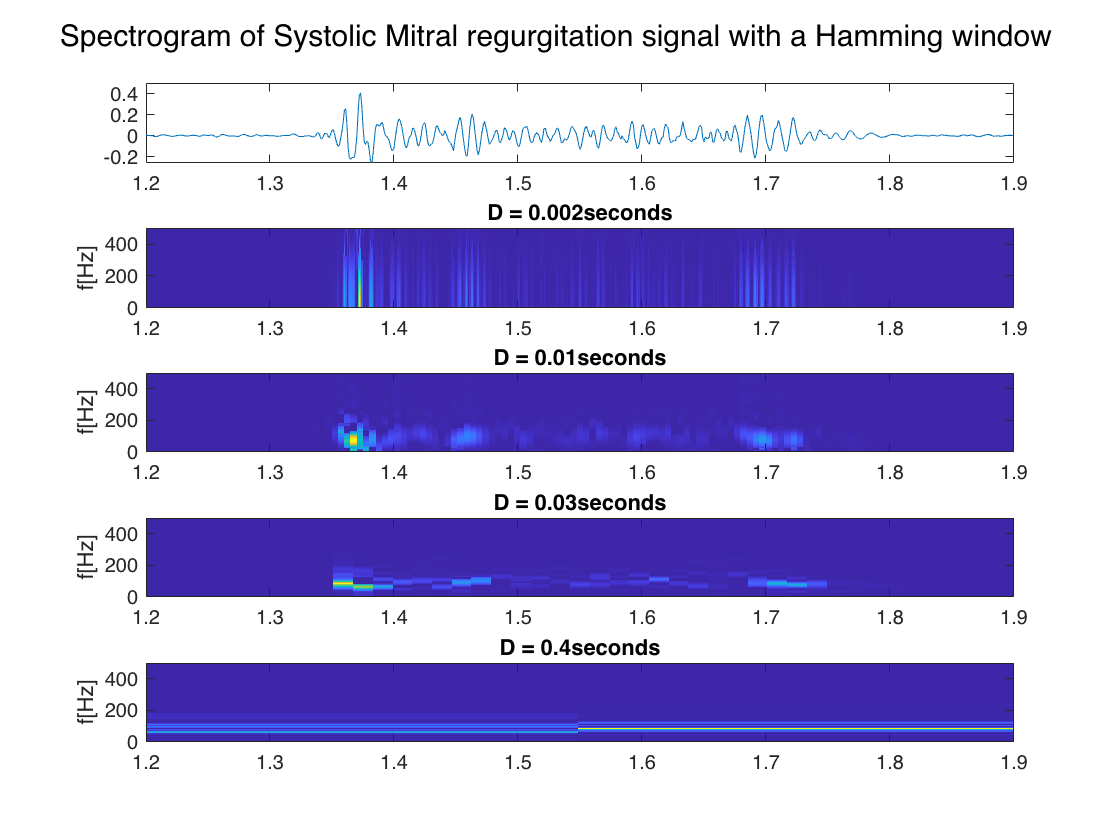

Nridges=0;
fdetection=0;

D= [0.002,0.01,0.03,0.4]*fs;

penval=1;
reassign=1; %Reassigned
umbral = 0; %No threshold
type=1; %0 for rectangular and 1 for hamming

signaltype='Systolic Mitral regurgitation';
windowtype = 'Hamming';
myspectogram(sysregurg,fs,t_sysregurg,D, type, umbral, penval, Nridges, fdetection, reassign, signaltype, windowtype)

*Discussion: *Nonetheless, the spectrogram is unsuitable for many contexts for two main reasons. The first reason, of a practical nature, is linked to the antagonism between the spectrogram’s temporal and frequency resolutions